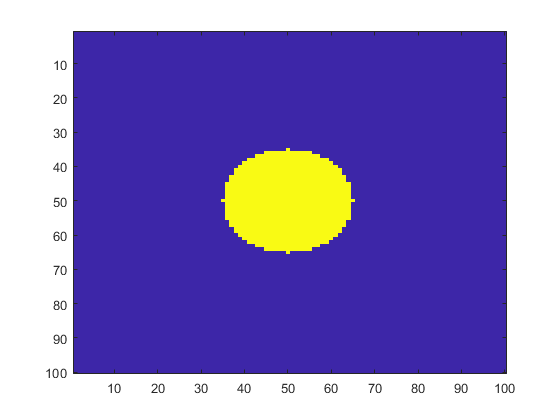

clear all
clf
colormap default


% Grid parameters
grid_size = 100; % Size of the grid
x_range = linspace(0, grid_size, grid_size); % X-axis range
y_range = linspace(0, grid_size, grid_size); % Y-axis range
[x, y] = meshgrid(x_range, y_range); % Create a 2D grid

% Static circle parameters
center_static = [50, 50]; % Center of the static circle
radius_static = 15;       % Radius of the static circle
% Create binary mask for the static circle
static_circle_mask = zeros(grid_size,grid_size);

for i = 1:length(x_range)
    for j = 1:length(y_range)
        
        if  sqrt((i - center_static(1)).^2 + (j - center_static(2)).^2) <= radius_static
            static_circle_mask(i,j) = 1;
        else           
            static_circle_mask(i,j) = -1;
        end
        
    end
end
%static_circle_mask(20,20) = 10;


%Calculate fieldstrength

for i = 1:length(x_range)
    for j = 1:length(y_range)
        static_circle_mask(i,j) = 0;
        
        for ii = 1:length(x_range)
            for jj = 1:length(y_range)
                static_circle_mask(i,j) = static_circle_mask(i,j) + 

        
            end
        end   

    
    end
end




imagesc(static_circle_mask)

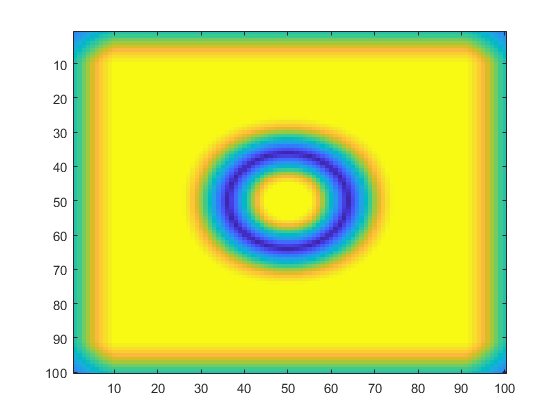








% Moving circle parameters
radius_moving = 10;       % Radius of the moving circle
move_range = linspace(30, 70, grid_size); % Range for moving circle positions
dynamic_circle_mask = zeros(grid_size,grid_size);

heatmap_matrix = zeros(grid_size,grid_size);
heatmap_matrix_ans = zeros(grid_size,grid_size);

% Calculate weighted common area
for center_dynamic_x = 1:length(x_range)
    for center_dynamic_y = 1:length(y_range)
        
      
        for ii = 1:length(x_range)
            for jj = 1:length(y_range)
                if  sqrt((ii - center_dynamic_x).^2 + (jj - center_dynamic_y).^2) <= radius_moving
                    heatmap_matrix_ans(center_dynamic_x,center_dynamic_y) =...
                    heatmap_matrix_ans(center_dynamic_x,center_dynamic_y) +...
                    static_circle_mask(ii,jj);
                else           
                    heatmap_matrix_ans(i,j) = 0;
                end
                
           
            end
        end
        heatmap_matrix_ans(center_dynamic_x,center_dynamic_y) = ...
        abs(heatmap_matrix_ans(center_dynamic_x,center_dynamic_y));
    end
end

imagesc(heatmap_matrix_ans)